# MCIR Test Bench

This test bench verifies that changes to MCIR still produce correct results. Verify that every assertion is successful. Errors or failed assertions indicate that the MCIR library is not functioning correctly.

import MCIR.*

% Test basic DC voltage divider circuit (Voltage and Resistor)
cir_name = "Test 1 - Voltage Divider, DC";
CIR1 = Circuit(cir_name);
CIR1 <= "V1 1 0 DC(10)"
CIR1 <= "R1 1 2 25k"
CIR1 <= "R2 2 0 75k"
dc = CIR1.dc

dc = 7.5000

assert(CIR1.name==cir_name)       % check that the name is correct
assert(abs(dc-7.50)<1e-6)         % check that result is correct
assert(length(CIR1.devices)==3)   % check that the circuit has the correct number of devices

% Test copy method, rename method, and initial condition on capacitor
new_name = "Test 2 - Voltage Divider, DC, with Initial Condition";
CIR2 = CIR1.copy;
CIR2.name = new_name;
CIR2 <= "C1 2 0 10p IC=6.0"
dc = CIR2.dc

dc = 6

assert(abs(dc-6.00)<1e-6)         % check for correct result - proves capacitor was added and IC was calculated
assert(CIR2.name==new_name)       % check for successful name change
assert(abs(CIR1.dc-7.50)<1e-6)    % check that CIR1 is not changed

% Test series resistance in voltage source
CIR3 = Circuit("Test 3 - Voltage Source, Rser");
CIR3 <= "V1 1 0 DC(10) Rser=50k"
CIR3 <= "R1 1 0 50k"
dc = CIR3.dc

dc = 5.0000

assert(abs(dc-5.00)<1e-6)        % check that internal V1 resistance results in voltage divider with R1

% Test component alteration, list
CIR4 = CIR3.copy;
CIR4.circuit_name = "Test 4 - Component parameter alteration";
CIR4.alter('R1','25k')
CIR4.alter('V1','Rser=75k')
CIR4.list

* Test 4 - Component parameter alteration
V1 1 0 DC=10 RSER=75k
R1 1 0 25k


dc = CIR4.dc

dc = 2.5000

assert(abs(dc-2.50)<1e-6)
assert(CIR4.list==("* Test 4 - Component parameter alteration" + newline + "V1 1 0 DC=10 RSER=75k" + newline + "R1 1 0 25k"))

% Test current source, Rpar, auto-numbering, output
CIR5 = Circuit("Test 5 - Current Source, DC");
CIR5 <= 'I@ 0 1 DC(0.1) Rpar=10'
CIR5 <= 'R@ 1 2 2'
CIR5 <= 'R2 2 3 3'  % auto-number should skip this one since it exists
CIR5 <= 'R@ 3 0 5'
CIR5 <= "OUT V(1)"
CIR5.list

* Test 5 - Current Source, DC
I1 0 1 DC=100m RPAR=10
R1 1 2 2
R2 2 3 3
R3 3 0 5
OUT V(1)


dc = CIR5.dc

dc = 0.5000

assert(abs(dc-0.5)<1e-6)
assert(CIR5.list==("* Test 5 - Current Source, DC" + newline + ...
                   "I1 0 1 DC=100m RPAR=10" + newline + ...
                   "R1 1 2 2" + newline + ...
                   "R2 2 3 3" + newline + ...
                   "R3 3 0 5" + newline + ...
                   "OUT V(1)"))  % checks auto-numbering

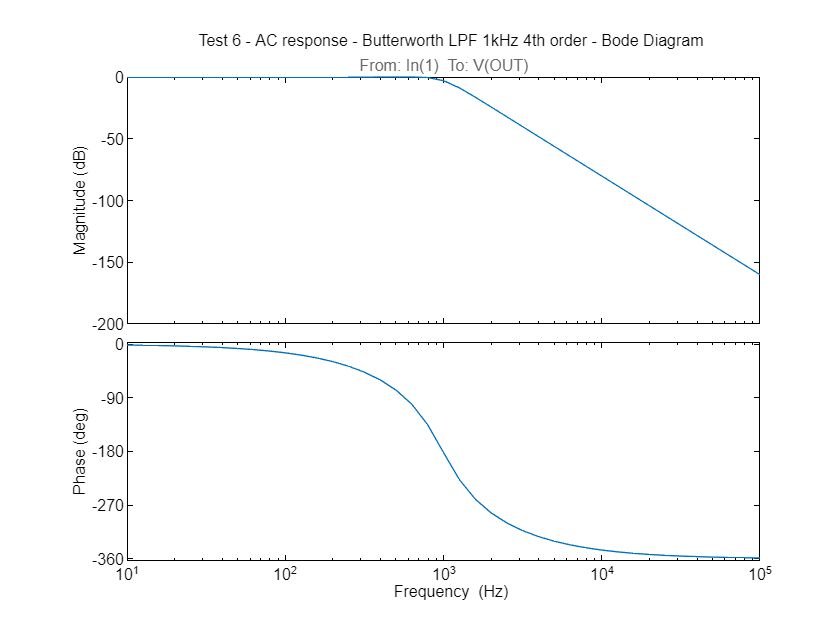

% Test AC frequency response, automatic V(OUT), capacitors, VCVS
CIR6 = Circuit("Test 6 - AC response - Butterworth LPF 1kHz 4th order");
CIR6 <= "Vin IN 0 AC(1)"
CIR6 <= "R1 IN 1 15.8k"
CIR6 <= "R2 1 2 15.8k"
CIR6 <= "C1 1 3 27n"
CIR6 <= "C2 2 0 3.9n"
CIR6 <= "E1 3 0 2 0 1.0"
CIR6 <= "R3 3 4 2.37k"
CIR6 <= "R4 4 5 1.05k"
CIR6 <= "C3 4 OUT 120n"
CIR6 <= "C4 5 0 82n"
CIR6 <= "E2 OUT 0 5 0 1.0"
CIR6.fr('dec',10,100e3,10)

% check that the response is correct
[H,F] = CIR6.fr('dec',10,100e3,10);
assert(abs(F(1)-10)<1e-6)
assert(abs(F(41)-100000)<1e-6)
assert(abs(abs(H(1))-1.0)<1e-4)
assert(abs(abs(H(20))-0.9758)<1e-4)
assert(abs(abs(H(30))-2.5061e-4)<1e-8)

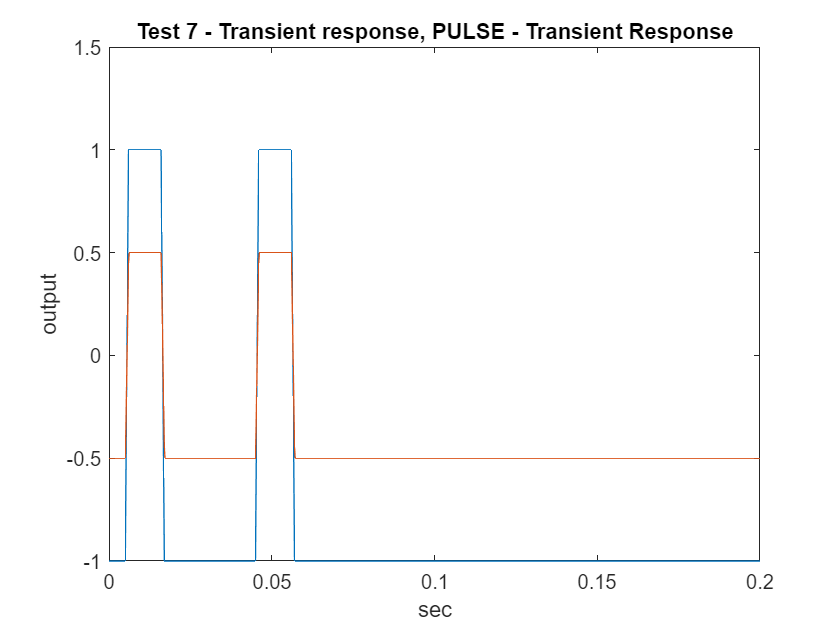

% Test transient response, pulse source, plotting specific variables
CIR7 = Circuit("Test 7 - Transient response, PULSE");
CIR7 <= 'V1 1 0 PULSE(-1 1 5m 1m 1m 10m 40m 2)'
CIR7 <= 'R1 1 2 10k'
CIR7 <= 'R2 2 0 10k'
CIR7 <= 'C1 2 0 10n'
CIR7 <= 'O1 V(1) V(2)'
CIR7.tr('200m',1001)

% check that the response is correct
[Y,T] = CIR7.tr('200m',1001);
assert(T(1)==0)
assert(abs(T(251)-0.05)<1e-6)
assert(abs(T(1001)-0.2)<1e-6)
assert(abs(Y(1,1)+1)<1e-6)
assert(abs(Y(1,2)+0.5)<1e-6)
assert(abs(Y(251,1)-1)<1e-6)
assert(abs(Y(251,2)-0.5)<1e-6)

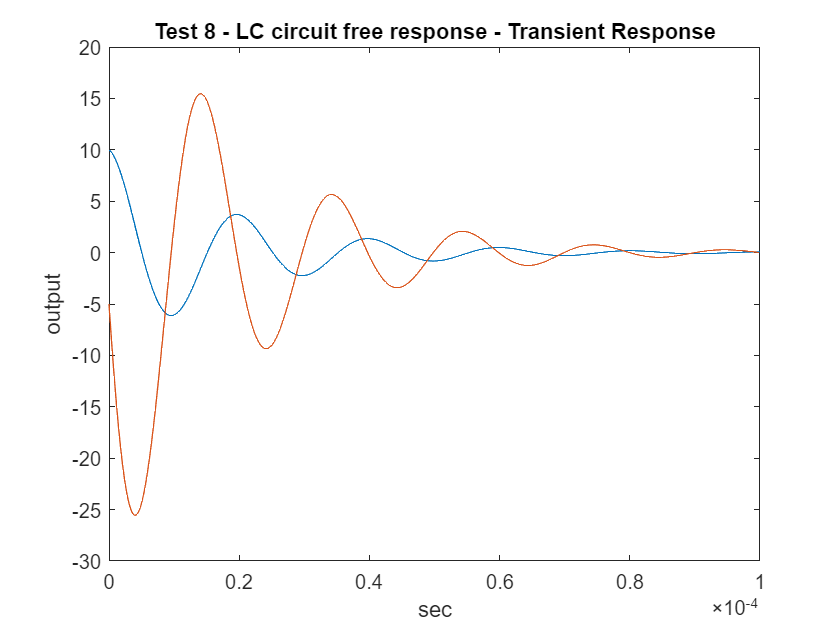

% Test inductor, initial condition, transient response
CIR8 = Circuit("Test 8 - LC circuit free response");
CIR8 <= "L1 0 1 1u Rser=0.1 IC=-5"
CIR8 <= "C1 1 0 10u IC=10"
CIR8 <= "OUT VC(C1) I(L1)"
CIR8.tr("0.09999m", 1001)

% check that the response is correct
[Y,T] = CIR8.tr("0.09999m", 1001);
assert(abs(Y(1,1)-10)<1e-5)
assert(abs(Y(1,2)+5)<1e-5)
assert(abs(min(Y(:,2))+25.5473)<1e-4)
assert(abs(max(Y(:,2))-15.4476)<1e-4)
assert(abs(max(Y(100:end,1))-3.7033)<1e-4)

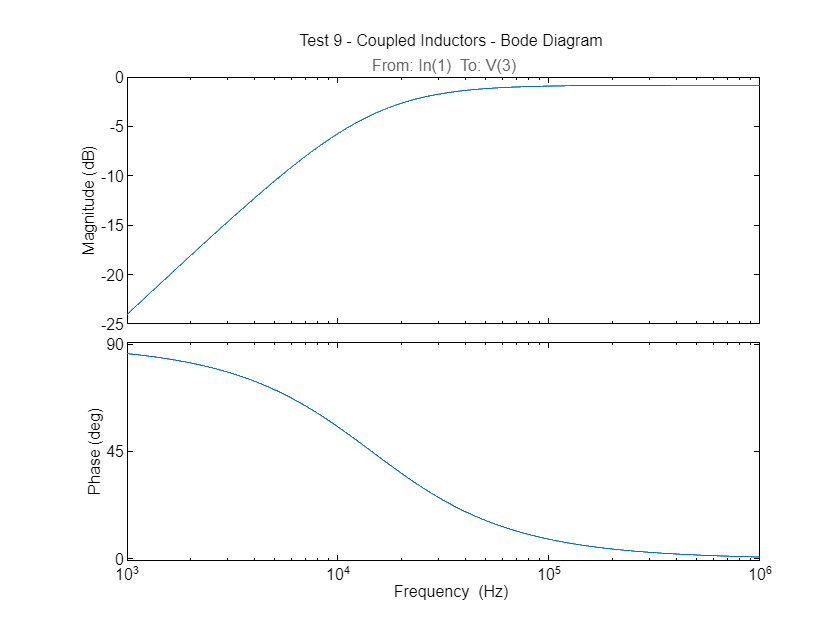

% Test coupling
CIR9 = Circuit("Test 9 - Coupled Inductors");
CIR9 <= "V1 1 0 AC(1)"
CIR9 <= "R1 1 2 10"
CIR9 <= "L1 2 0 10u"
CIR9 <= "L2 3 0 1000u"
CIR9 <= "R2 3 0 100"
CIR9 <= "K1 L1 L2 1.0"
CIR9 <= "OUT V(3)"
CIR9.ac(1e3, 1e6, 1001)

% check that the response is correct - just test one frequency
[H,F] = CIR9.ac(1e6);
assert((abs(H)-0.9089)<1e-4)

% Check dependent sources: VCVS, CCCS, VCCS, CCVS
CIR10 = Circuit("Test 10 - Dependent Sources");
CIR10 <= "Vin in 0 DC=1"
CIR10 <= "R1 in 1 99k"
CIR10 <= "R2 1 0 1k"
CIR10 <= "Ex 2 0 1 0 10.0"
CIR10 <= "Fx 2 0 Vx 0.1"
CIR10 <= "Gx 0 3x 2 0 0.01"
CIR10 <= "Vx 3x 3 0.0"
CIR10 <= "Hx 3 0 Vx 10"
CIR10.dc

Test 10 - Dependent Sources - Operating Point report:
V(3)	10m


v = CIR10.dc;
assert(abs(v-0.01)<1e-6)

% Check nullor
CIR11 = Circuit("Test 11 - Nullor");
CIR11 <= "Vin 1 0 DC=1m"
CIR11 <= "R1 1 x 10k"
CIR11 <= "R2 x 2 100k"
CIR11 <= "N1 2 0 x 0"
CIR11.dc

Test 11 - Nullor - Operating Point report:
V(2)	-10m


v = CIR11.dc;
assert(abs(v+0.01)<1e-6)

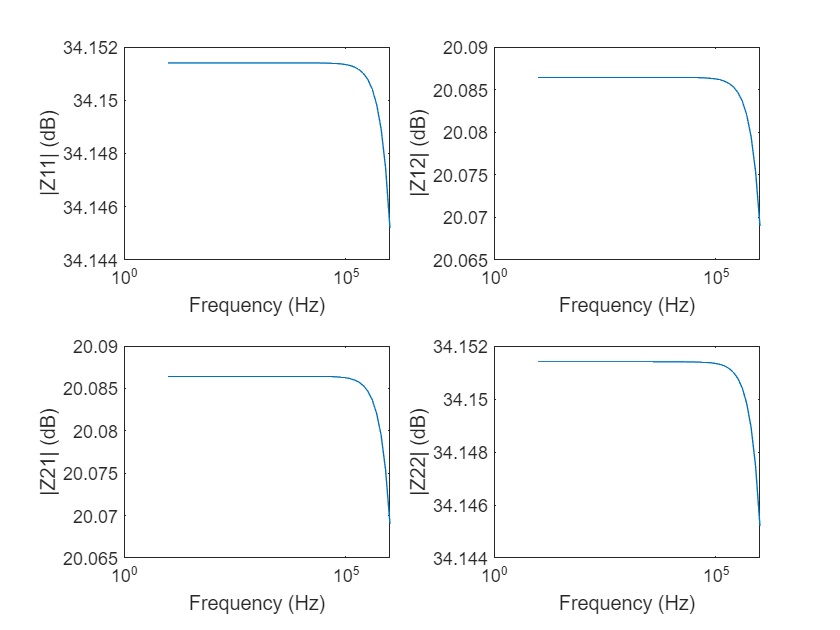

% Check multi-port network analysis
CIR12 = Circuit("Test 12 - 2-port Network");
CIR12 <= 'PORT1 1 0 50'
CIR12 <= 'R1 1 2 40.9'
CIR12 <= 'R2 2 0 10.1'
CIR12 <= 'C1 2 0 1000p'
CIR12 <= 'R3 2 3 40.9'
CIR12 <= 'PORT2 3 0 50'
CIR12.net('Z', 'dec',10,1e6,10)

Z = CIR12.net('Z', [10 10e6]);
Zf = Z.Data(:,:,2);
assert(abs(abs(Zf(1,1))-48.3168)<1e-4)
assert(abs(abs(Zf(1,2))-8.5278)<1e-4)


% subcircuits
FOO = Subcircuit("FOO");
FOO <= "PINS in out com"
FOO <= "R1 in x 10k"
FOO <= "R2 x com 1k"
FOO <= "R3 x out 10k"
FOO <= "C1 x com 100n"
FOO.list

SUBCIRCUIT FOO(IN, OUT, COM)
R1 IN X 10k
R2 X COM 1k
R3 X OUT 10k
C1 X COM 100n
END SUBCIRCUIT FOO


Subcircuit.Library

FOO(3)


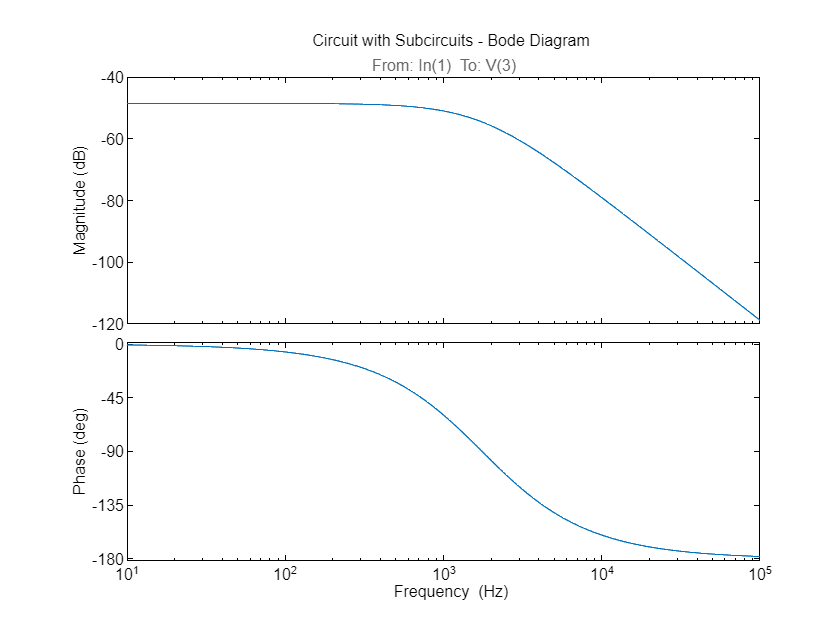

CIR13 = Circuit("Circuit with Subcircuits");
CIR13 <= "Vin 1 0 AC=1"
CIR13 <= "X1 FOO 1 2 0"
CIR13 <= "X2 FOO 2 3 0"
CIR13 <= "R2 3 0 100k"
CIR13 <= "OUT V(3)"
CIR13.ac(10.0, 100e3, 100)

%%%% !!!! all internal voltages other than those mapped to pins need to be
%%%% mangled with X?.node:  something like V(X) becomes V(X1.X) if X is a
%%%% node inside the subcircuit